Import data

species_dataset = xlsread("C:\Users\hgmchau\Downloads\data_file.xls");
data = cell(1,13);
for i = 1:13
    data{i} = species_dataset(species_dataset(:,3)==i,:);
end
species = ["Guppy" "Heron" "Hen" "Salmon" "Rat" "Cod" "Robin" "Shrew" "Guinea Pig" "Dom Rabbit" "Dom Pig" "Cow" "Shrimp"];
d = dictionary(species,data);

Fit equation to data - Guppy

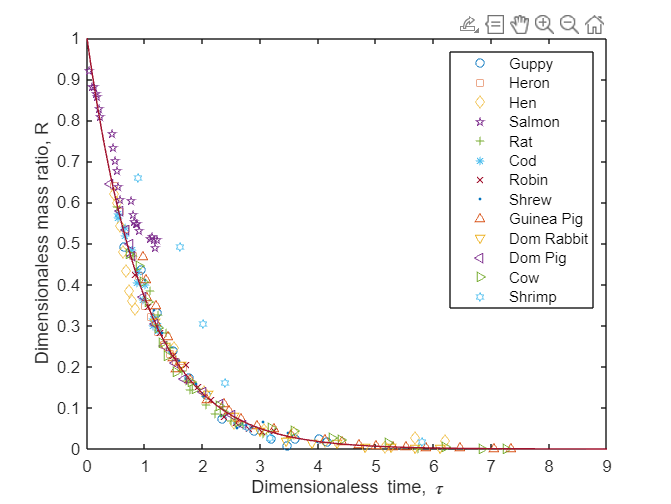

% Get data of species Guppy
v = values(d);
% Values of parameters
a = [0.1 1.56 0.47 0.026 0.23 0.017 1.9 0.83 0.21 0.36 0.31 0.28 0.027];
m0 = [0.008 3 43 0.01 8 0.1 1 0.3 5 120 900 33300 0.008];
M = [0.15 2700 2100 2400 280 25000 22 4.2 840 1350 320000 442000 0.075];
new_data = cell(1,13);
% Rescale all data
for i = 1:13
    new_data{i} = [a(i)*data{i}(:,1)/(4*M(i).^(1/4))-log(1-(m0(i)/M(i)).^(1/4)),1-(data{i}(:,2)/M(i)).^(1/4)];
end
newd = dictionary(species,new_data);
newv = values(newd);
x = linspace(0,9,500);
y = exp(-x);
% Plot the dimensionaless-data
marker = ['o' 's' 'd' 'p' '+' '*' 'x' '.' '^' 'v' '<' '>' 'h'];
for i = 1:13
    plot(newv{i}(:,1),newv{i}(:,2),marker(i),'MarkerSize',5);
    hold on
end
hold on;
plot(x,y);
ylim([0,1]);
xlabel('Dimensionaless time, \tau');
ylabel('Dimensionaless mass ratio, R');
legend("Guppy", "Heron", "Hen", "Salmon", "Rat", "Cod", "Robin", "Shrew", "Guinea Pig", "Dom Rabbit", "Dom Pig", "Cow", "Shrimp",'Location','northeast','Orientation','vertical')

% plot(v{9}(:,2),v{9}(:,1),'.','MarkerSize',10,'MarkerEdgeColor','red','Color','red');


Local function - Growth curve

function m = ontogenetic_growth(para_fit,t)
a = para_fit(1);
m0 = para_fit(2);
M = para_fit(3);
m = M*(1-(1-(m0/M)^(1/4))*exp(-a*t/(4*M^(1/4)))).^4;
end